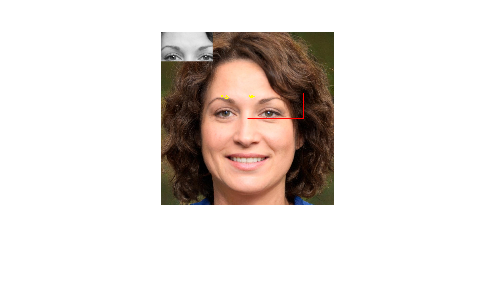

I = masOjos;
iniciox = 1;
inicioy = round(2*width(I)/11);

I = I(iniciox:height(I), inicioy:round(7*width(I)/9), :);
grises = rgb2gray(I);
hold on;
imshow(grises);
hold off;

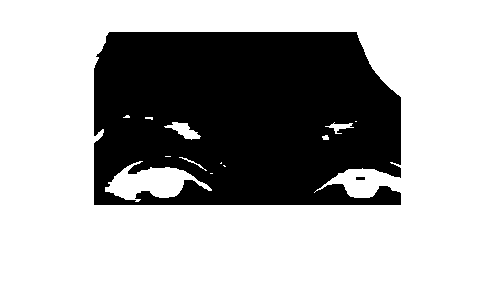

binarizada = grises < 110;
cerrada = imclose(binarizada, [1 1 1 1 1 1 1 1 1]);
imshow(cerrada);
hold on;

iniciox = round(width(I)/2 + center(1));
inicioy = round(60 + center(2) - 30);
plot(iniciox, inicioy, 'o');
hold off;

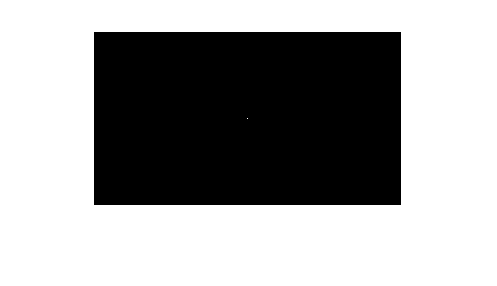

% primeraCeja = round(inicioy);
% while (primeraCeja > 0)
%     if (cerrada(primeraCeja, iniciox) == 1)
%         break;
%     end
%     primeraCeja = primeraCeja - 1;
% end
% 
% cejaIzquierda = [iniciox primeraCeja];
% 
% segundaCeja = cejaIzquierda(1) - 50;
% while (segundaCeja > 0)
%     if (cerrada(primeraCeja, segundaCeja) == 1)
%         break;
%     end
%     segundaCeja = segundaCeja - 1;
% end

canvas = false([height(I) width(I)]);
canvas(round(height(canvas)/2), round(width(canvas)/2)) = 1;
imshow(canvas);

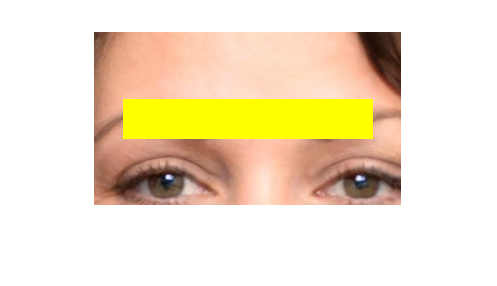

canvas = imdilate(canvas, strel('rectangle', [40 250]));
imshow(imoverlay(I, canvas));

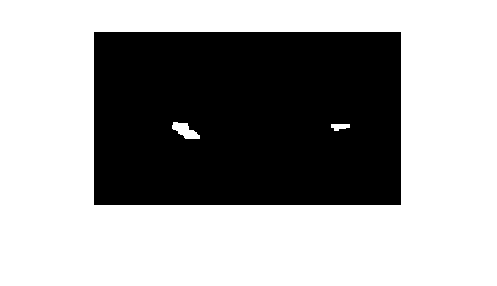

reconstruccion = imopen(canvas & cerrada, strel('square', 4));
imshow(reconstruccion);

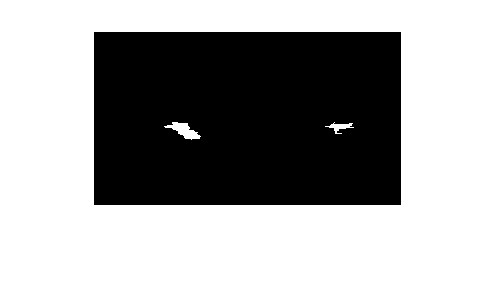

i = 0;
while(i < 100)
    temporal = imdilate(reconstruccion, strel('square', 5));
    reconstruccion = temporal & cerrada;
    i = i + 1;
end
imshow(reconstruccion);

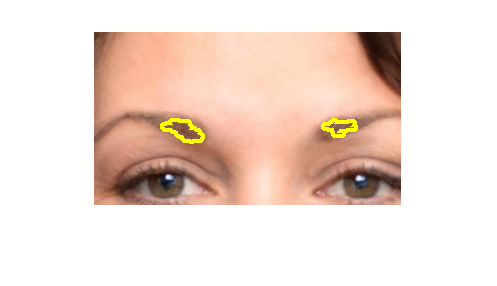

marcas = imdilate(reconstruccion, strel('disk', 5)) - reconstruccion;
imshow(imoverlay(I, marcas));

jmin = round(width(I)/2);
while (jmin > 0)
    if (sum(marcas(:, jmin)) > 1)
        break;
    end
    jmin = jmin - 1;
end

jmax = round(width(I)/2);
while (jmax < width(I))
    if (sum(marcas(:, jmax)) > 1)
        break;
    end
    jmax = jmax + 1;
end

distancia = jmax - jmin;

%msgbox("La distancia es " + int2str(distancia));

inicioVertical1 = inicioVerticalMas;
inicioHorizontal1 = inicioHorizontal + (round(2*width(masOjos) * factorInverso/11));

cejasRes = false([height(caraMarcada) width(caraMarcada)]);
cejasRes(inicioVertical1:(inicioVertical1 + height(marcas) - 1), inicioHorizontal1:(inicioHorizontal1 + width(marcas) - 1)) = marcas;

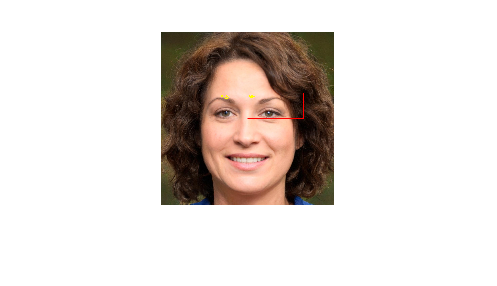

imshow(imoverlay(caraMarcada, cejasRes));

%imshow(cejasRes)